# **Identification and Estimation**

# **Exam December 8**

# **9 am to 11 am**

**Open book, open internet, no communication with human beeing allowed**

This exam is a "matlab live script" : a format that mix text and executable code. Each "section" can be run separately (Tab LIVE EDITOR/Run Section). The outputs is shown on right.

You will be asked:

- to complete, modify and comment matlab code. (into "code" sections)

- to answer literal questions (into "text" sections)

## **I. Exercice 1: Identification**

The goal is to find a discrete model from a set of data. The data is made of N=1000 samples, the input is a pseudo random binary signal.

First load and visualize the data:

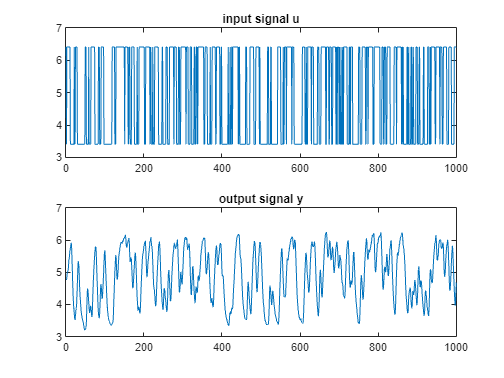

close all;
load data_ident.mat
t=1:length(u);
figure(1);
subplot(211);plot(t,u);title('input signal u');
subplot(212);plot(t,y);title('output signal y');

A linear model $\frac{y}{u}=\frac{B}{A}$ can be obtained by choosing an appropriate methode (recursive least square or extended least square) and number of coefficients (na,nb,nc and delay d). All the functions are provided and do not need to be modified.

**Identification with a Recursive least Square method.**

Choice of dimensions

na=2; % TUNE
nb=1; % TUNE
d=6; % Delay : enforces the first (d+1) parameters of B to be equal to zero % TUNE

Find a model

[A,B] = rls( y, u, na, nb, d );

Compute and visualize residuals (the two blue lines are the whiteness interval $\pm \frac{2\ldotp 17}{\;\sqrt{N}}$)

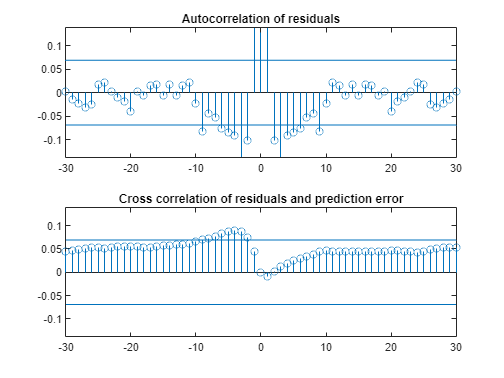

[err,yhat] = errpred_rls(y,u,A,B);
figure(2);
plotresiduals(err,yhat);

**Identification with an Extended Least Square method.**

Choice of dimensions

nc=2; % TUNE

Find a model

[A,B,C] = els( y, u, na, nb, nc,d );

Compute and visualize residuals  (the two blue lines are the whiteness interval $\pm \frac{2\ldotp 17}{\;\sqrt{N}}$)

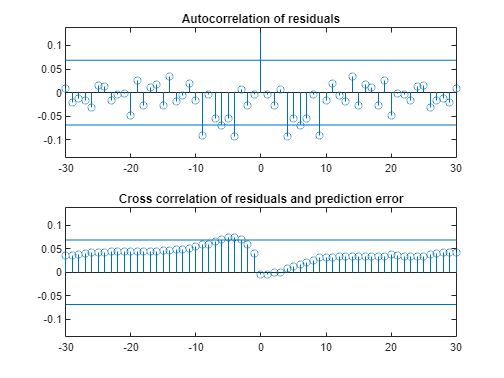

[err,yhat] = errpred_els(y,u,A,B,C);
figure(3);
plotresiduals(err,yhat)

### **Question 1 : (8 points)**

The code given in the previous section is very basic. All the parameters are set to 1 and no preprocessing of data as been done.

Modify the code (trying other values for na,nb,nc and d) and propose the "best" model. You will explain what you mean by "best" model and how you validate it. (na max and nb max are 3, nc max is 6, d max is 4)

### **Question 2 : (2 points)**

Plot the step response of your "best model". What is the static gain?

What is the time constant?

## **II. exercice 2 : Kalman filtering **

A discrete process is driven by the linear discrete equation:


$$\begin{array}{l}
x\left(t+1\right)=0\ldotp 99*x\left(t\right)+e\left(t\right)+u\left(t\right)\\
y\left(t\right)=x\left(t\right)+v\left(t\right)
\end{array}$$


where :

- $x\left(t\right)$ is the internal state

- $e\left(t\right)$ is a control input

- $u\left(t\right)$ is a zero mean random noise (gaussian distribution, known variance Q=0.05)

- $v\left(t\right)$ is a zero mean random noise (gaussian distribution, known variance R=1)

In the following code we simulate the output when the input is a pseudo random binary signal. The "real" state x(t) is simulated and will be estimated in the next questions. (This section must be executed before the next ones).

%init
close all;
N=500; %number of samples
x = zeros(1,N);
y =zeros(1,N);
e = 0.1*idinput(N,'prbs');% prbs signal

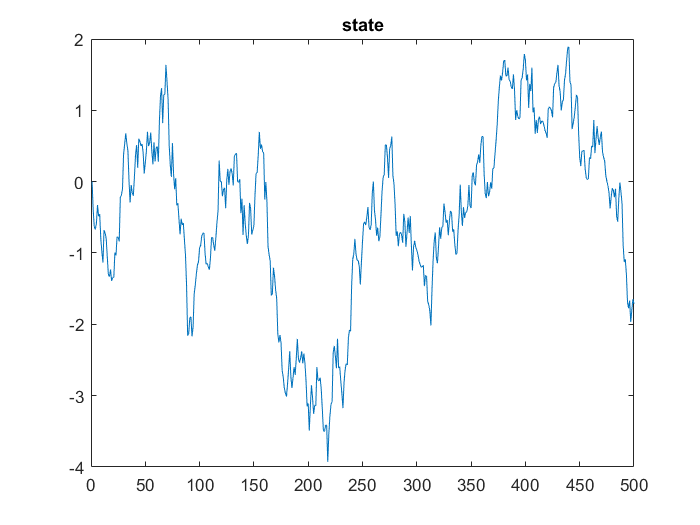

Qreal=0.05; %variance of the additive state noise
Rreal=1;%variance of the additive measurement noise

%Simulation of the "real" signals
for t=2:N
    %simulate output and internal state
    x(t) = 0.99*x(t-1) + e(t) + sqrt(Qreal)*randn(1);
    y(t) = x(t) + sqrt(Rreal)*randn(1);
end
plot(1:N,x);title('state')

### Question 3 : code the Kalman filter in order to estimate x_1(t)  (5 points)

We want to compute the estimate xe(t) of the state x(t) using only the known input e(t) and measured output y(t).

Complete and modify the following code in order to achieve this filtering. (You must modifi the initial settings (P, Q, R, xe) and code the Kalman filter into the loop.

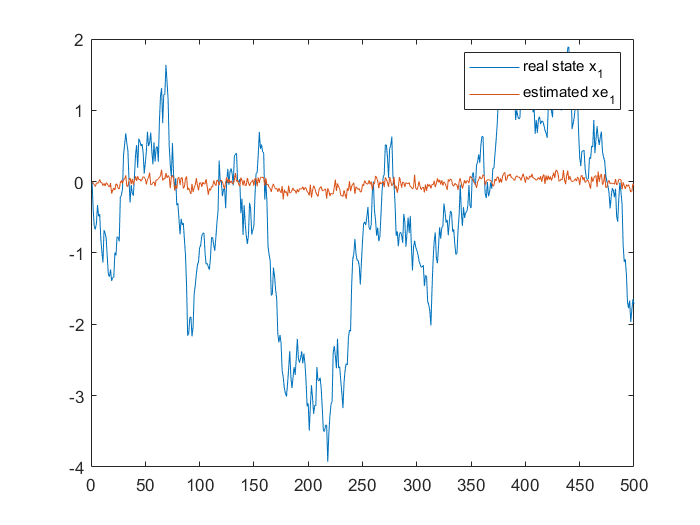

P=1; %initial value of the filter covariance error (Kalman filter) TUNE
Q=Qreal; %variance of the additive filter state noise 
R=Rreal;%variance of the additive filter measurement noise
xe_1=0; %inial value of the filter estimated state 1
ypred=0;

for t=2:N
    %estimate the state x(t)
    %your code begins here
    %predict
    xe_1(t)=0; % REPLACE
    A=0; % REPLACE
    P=A*P*A'+Q;
    %Update
    ypred(t)=0; % REPLACE
    C=1; % REPLACE
    K=P*C'*inv(C*P*C'+R);
    P=P-K*C*P;
    xe_1(t)=xe_1(t)+K*(y(t)-ypred(t));
    %end of your code
end
close all;
plot(1:N,x,1:N,xe_1);legend('real state x_1','estimated xe_1');

### Question 4 :  (5 points)

The dynamic gain $0\ldotp 99$ is unknown and we want now to estimate it with an extended Kalman filter. The equations to consider are:


$$\begin{array}{l}
x_1 \left(t+1\right)=x_2 \left(t\right)*x_1 \left(t\right)+e\left(t\right)+u\left(t\right)\\
y\left(t\right)=x_1 \left(t\right)+v\left(t\right)
\end{array}$$


where :

- $x\left(t\right)=\left\lbrack \begin{array}{c}
x_1 \left(t\right)\\
x_2 \left(t\right)
\end{array}\right\rbrack$ is the internal state of dimension 2

Complete and modify the following code in order to achieve this filtering. (You must modifi the initial settings (P, Q, R, xe) and code the Kalman filter into the loop.

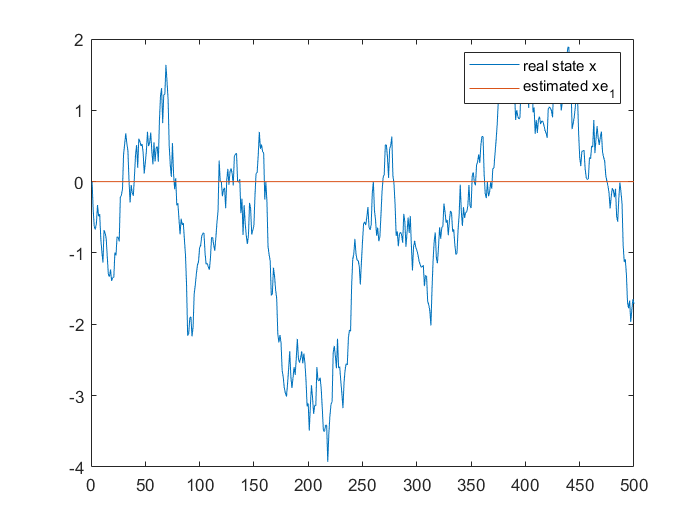

P=[1 0
    0 1]; %initial value of the filter covariance error (Kalman filter) TUNE
Q=[Qreal 0;
    0 1]; %variance of the additive filter state noise TUNE
R=Rreal;%variance of the additive filter measurement noise
xe_1=0; %initial value of the filter estimated state 1
xe_2=0; %initial value of the filter estimated state 2
ypred=0;

for t=2:N
    %estimate the state x(t)
    %your code begins here
    %predict
    xe_1(t)=0; % REPLACE
    xe_2(t)=0; % REPLACE
    A = [0 0
        0 0]; % REPLACE
    P=A*P*A'+Q;
    %Update
    ypred(t)=0; % REPLACE
    C=[0 0]; % REPLACE
    K=P*C'*inv(C*P*C'+R);
    P=P-K*C*P;
    xe_1(t)=xe_1(t)+K(1)*(y(t)-ypred(t));
    xe_2(t)=xe_2(t)+K(2)*(y(t)-ypred(t));
    %end of your code
end
plot(1:N,x,1:N,xe_1);legend('real state x','estimated xe_1');

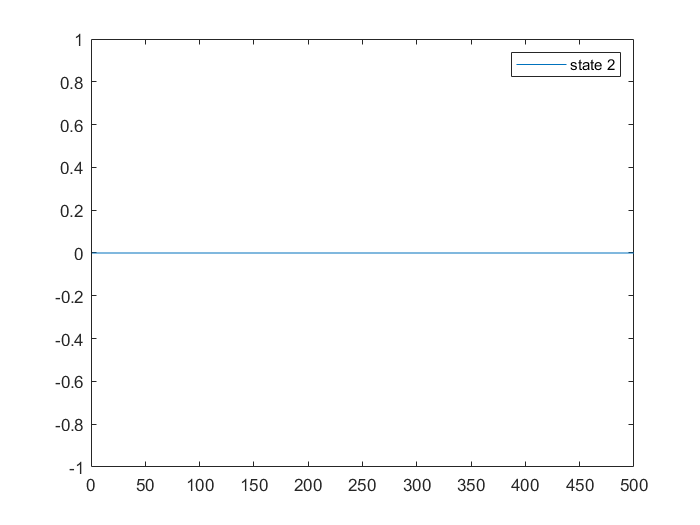

plot(1:N,xe_2);legend('state 2');